# 1. Describe Raw Data

#### Load raw data into a variable valled output

delete("Raw_1001.mat");

D=dir('Raw_*.mat');
filename={D.name};
output=zeros(1,(length(filename)*(26000))); % this number needs to be the length of aData

for i=1:length(D)
    load(filename{i});
    output(((i-1)*(26000)+1):(i*(26000)))=temp;
end

#### Create a handle to output for each channel

totalLen = length(output);
numChannels=13;
Ch1=find(mod(1:totalLen,numChannels)==1);   % Ch1: photodetector green
Ch2=find(mod(1:totalLen,numChannels)==2);   % Ch2: photodetector red
Ch3=find(mod(1:totalLen,numChannels)==3);   % Ch3: DAC0 167Hz Mod Copy (green)
Ch4=find(mod(1:totalLen,numChannels)==4);   % Ch4: DAC1 223Hz Mod Copy (red)
Ch5=find(mod(1:totalLen,numChannels)==5);   % Ch5: Threat
Ch6=find(mod(1:totalLen,numChannels)==6);   % Ch6: Start
Ch7=find(mod(1:totalLen,numChannels)==7);   % Ch7: Lick/reward

#### Assign raw data for each channel of interest to named variables

PD_green        =output(Ch1);
PD_red          =output(Ch2);
Mod_green       =output(Ch3);
Mod_red         =output(Ch4);
align_threat    =output(Ch5);
align_start     =output(Ch6);
align_l_r       =output(Ch7);

#### Plot each channel of interest

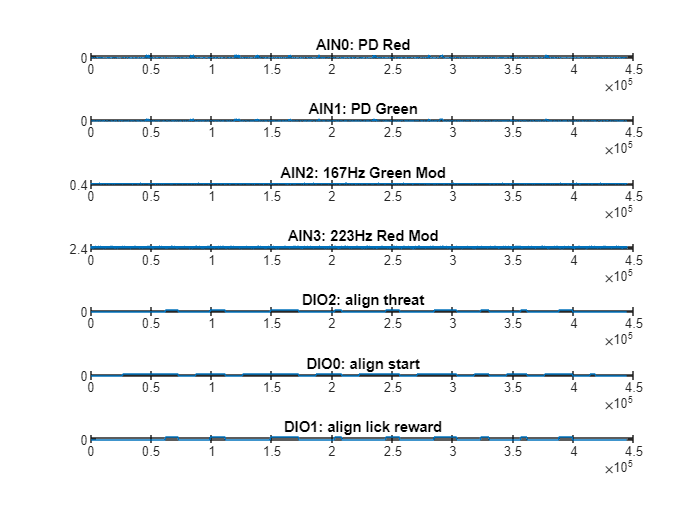

figure;
ax = [];
ax(1) = subplot(7,1,1);plot(PD_red);title('AIN0: PD Red')
ax(2) = subplot(7,1,2);plot(PD_green);title('AIN1: PD Green')
ax(3) = subplot(7,1,3);plot(Mod_green);title('AIN2: 167Hz Green Mod');ylim([0.35 0.65]);
ax(4) = subplot(7,1,4);plot(Mod_red);title('AIN3: 223Hz Red Mod');%ylim([0.35 0.65]);
ax(5) = subplot(7,1,5);plot(align_threat);title('DIO2: align threat')
ax(6) = subplot(7,1,6);plot(align_start);title('DIO0: align start')
ax(7) = subplot(7,1,7);plot(align_l_r);title('DIO1: align lick reward')

linkaxes(ax,'x');

# 2. Demodulate Photodetector Signals

Set min and max values for params.freqRange1 and params.freqRange2 so each range spans the target oscillation frequency of that channel, and (ideally) excludes the oscillation on the opposite channel

The most useful output variables are:

-     dsTimes                            -- the time stamps of the output data

-     rawVals1 & rawVals2        -- output data before photobleaching correction

-     dsVals1 & dsVals2            -- photobleaching corrected data for channels 1 and 2

-     syncInTimes                     -- timestamps of TTL events on SyncIn channel

-     syncOutTimes                  -- timestamps of TTL events on SyncOut channel

% Creates a params struct
params.freqStep   = 5;          % Step size in Hz for freqency calculations
params.freqRange1 = [125 200];  % Min and max frequency range for channel 1 (target 167 Hz) (ex 125-200)
params.freqRange2 = [200 275];  % Min and max frequency range for channel 2 (target 223 Hz) (ex 200-275)
params.winSize = 0.04;          % Target window size (in sec) for FFT frequency calc (80 samples)
params.spectSample = 0.01;      % Step size for spectrogram (sec)
params.inclFreqWin = 4;         % Number of frequency bins to average (on either side of peak freq)
params.filtCut = 100;           % Cut off frequency for low pass filter of processed data
params.filtCutOsc = 500;        % Cut-off frequency for low-pass filter of oscillation data.
params.dsRate = 0.05;           % Time steps for down-sampling (seconds) (average of every 100 samples)

#### Calculate Spectrogram for Channel 1

useFreqRange = params.freqRange1(1):params.freqStep:params.freqRange1(2);
[filtTimes,filtSig1, rawSig1, spectFreqs1, spectAmpVals1] = sfoReadFibPhot(PD_green, 2000, useFreqRange, params);

Spectrum window 0.064 sec; 128 samples at 2000 Hz


#### Calculate Spectrogram for Channel 2

useFreqRange = params.freqRange2(1):params.freqStep:params.freqRange2(2);
[filtTimes,filtSig2, rawSig2, spectFreqs2, spectAmpVals2] = sfoReadFibPhot(PD_red, 2000, useFreqRange, params);

Spectrum window 0.064 sec; 128 samples at 2000 Hz


#### Determine downsampled time points in output data set

dsTimes = filtTimes(1):params.dsRate:filtTimes(end); 

#### Photobleaching Correction

% Fit: Fit each channel to exponential decay for photobleaching correction
pbFit1 = fit(filtTimes',filtSig1','exp2'); 

'fit' requires one of the following:
  Curve Fitting Toolbox
  Model-Based Calibration Toolbox
  Predictive Maintenance Toolbox
  SimBiology
  Statistics and Machine Learning Toolbox

pbFit2 = fit(filtTimes',filtSig2','exp2');

% Correction: Divide filtered signal by exponential decay to correct for photobleaching
pbVals1 = (filtSig1' ./ double(pbFit1(filtTimes)))';
pbVals2 = (filtSig2' ./ double(pbFit2(filtTimes)))';

% Downsample photobleaching-corrected data
dsVals1 = interp1(filtTimes,pbVals1,dsTimes,'spline');
dsVals2 = interp1(filtTimes,pbVals2,dsTimes,'spline');

% Downsample raw (uncorrected) data
rawVals1 = interp1(filtTimes,filtSig1',dsTimes,'spline');
rawVals2 = interp1(filtTimes,filtSig2',dsTimes,'spline');

# 3. Make dF/F

- g_dff = green channel

- r_dff = red channel

- running_percentile(x, win, p)

-     x = signal

-     win = number of points over which to take p

-     p = percentile of points to average (10 = minimum 10% of points)

Fs=20; 

g_0 = running_percentile(dsVals1, floor(Fs*60), 10);
g_dff = dsVals1'./g_0 - 1;
g_dff = g_dff';

r_0 = running_percentile(dsVals2, floor(Fs*60), 10);
r_dff = dsVals2'./r_0 - 1;
r_dff = r_dff';

% make derivative raw trace
% array loses 1 cell...

g_differ = diff(dsVals1');
r_differ = diff(dsVals2');
g_differ = g_differ';
r_differ = r_differ';
g_differ = [zeros(1, max(0, 1)), g_differ]; % add in zero to beginning of vector
r_differ = [zeros(1, max(0, 1)), r_differ];

#### Z-score raw trace and diff

zscore_dsval1 = zscore(dsVals1);
%zscore_dsval2 = zscore(dsVals2);

zscore_g_diff = zscore(g_differ);
%zscore_r_diff = zscore(r_differ);

#### Plot 

figure;
ax = [];

ax(1) = subplot(4,1,1);
plot(filtTimes,rawSig1); title('raw ds filt');
xlabel('Time (s)')
ylabel(' dF ')

ax(2) = subplot(4,1,2);
plot(dsTimes,dsVals2); title('dsVals');
xlabel('Time (s)')
ylabel(' dF ')

ax(3) = subplot(4,1,3);
plot(dsTimes,g_dff); title('g df/f');
xlabel('Time (s)')
ylabel(' dF/F_0')

ax(4) = subplot(4,1,4);
timetemp =linspace(0,length(Ch6)/2000,length(Ch6));
plot(timetemp, output(Ch6)); title('Pink Noise');

linkaxes(ax, 'x');

# 4. Align to behavioral events

% index to the start of each alignment pulse

ds_align_pink = interp1(timetemp,align_pink,dsTimes);
ds_align_peaks = find(ds_align_pink > 0.2);

ds_align_peaks_diff = find(diff(ds_align_peaks) > 10);
ds_align_spots = ds_align_peaks(ds_align_peaks_diff);

% idx = zeros(1,11979);
% idx(ds_align_spots) = 1
%trigAvg trigAvg(data, time, s_before, s_after, Fs)
[trigAvg, trigIndiv] = trigAvg(...
    dsVals1, ... data to align to events
    ds_align_spots, ... Indices of events to align to
    1, ... time before index
    3, ... time after index
    20 ... sampling rate (downsampled);
);
figure;
x=[];
y =trigIndiv';
figure;
plot(trigIndiv)
figure;
plot(trigAvg)
figure;
shadedErrorBar(x,mean(y,1),std(y));
figure;
sc = imagesc(trigIndiv')
ylabel("observations", "FontName",'Gill Sans MT',"FontSize",20)
set(gca,'XTick',[])
xline(40, "LineWidth",4,"Label","event","LabelOrientation","horizontal","LabelVerticalAlignment","bottom","FontSize",20,"FontName",'Gill Sans MT')


clear
clc